# `Double lane Change Manuever`

`Brian Lesko`

`Masters of Mechanical Engineering`

`Ohio State University `

`April 4, 2023`

`Dr. Levent Guvenc`

`Originally a Matlab and Simulink mardown file`

`By Brian Lesko, Graduate researcher and Teaching associate, Masters of mechanical engineering student`

`Inspired by Robust Controls of Mechatronic Systems, by Dr. Levent Guvenc`

# `Contents`

- `Contents`

- `Introduction `

- `Vehicle Parameters`

- `Simulink Model`

- `Controller Tuning `

- `Path Smoothness`

- `Effect of Vehicle Speed, Simulations `

- `Effect of Preview Length, Simulations`

- `Conclusion`

- `Functions`

# `Introduction`

`    The ability to accurately follow a given path enhances the safety and efficiency of the vehicle and also improves passenger comfort. To achieve optimal path-following performance, it is essential to properly tune the vehicle controller and shape the input path. By ensuring that the input path possesses a smooth derivative, sudden changes in the vehicle's motion can be minimized, thus preventing abrupt acceleration, deceleration, or steering actions. Consequently, an appropriately designed and tuned vehicle controller, combined with a well-shaped input path, contributes to a more seamless and enjoyable driving experience while maintaining safety and precision.`

# `Vehicle Parameters`

clc; clear; close all;
addpath('simulinkModels');

[L, g, Lr, Lf, Cf, Cr, m, J, mu, R, Cs, V, ls, a11, a12, a21, a22, b11, b12, b21, b22, e2, A_matrix, B_matrix, C_matrix, D_matrix] = getModel();

# `Simulink Model`

**Path Following Vehicle Model**

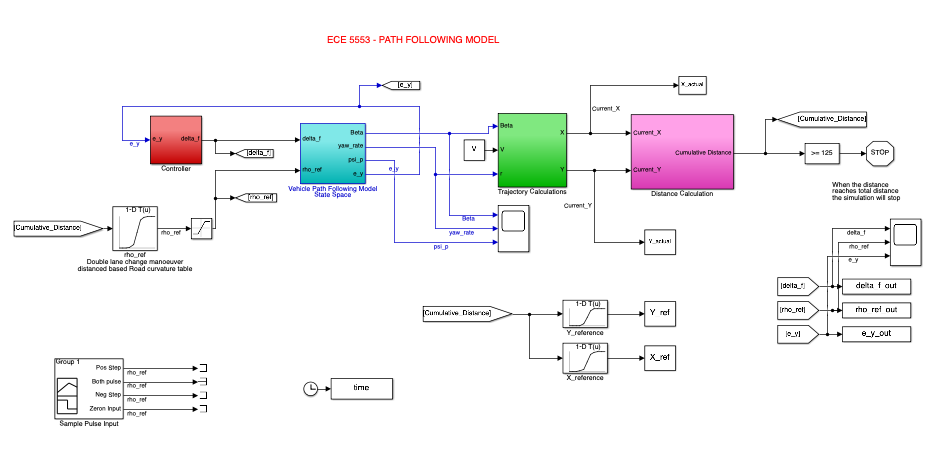

This path following model was provided without a tuned controller or path, the goal in this document is to shape the input path and controller to follow the double lane change manuever

# `Controller Tuning`

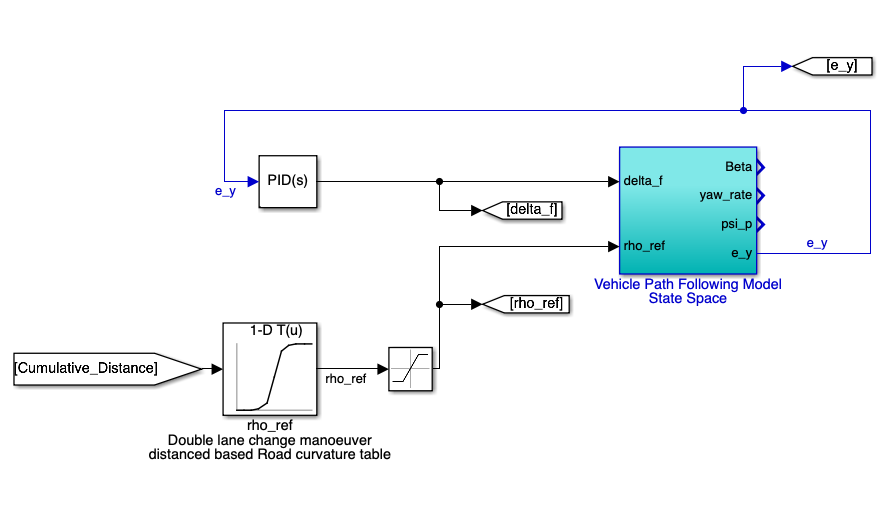

This subsection of the simulink model is extracted to utilize simulink's built in tuning feature, this extraction is necessary because the entire model cannot be linearized due to nonlinearity in the trajectory calculation block.

% which result in the gains as follows, when a lower robustness and higher
% speed is chosen
P = -1.5;
I = -5.5;
D = 0.0113;
N = 200;

# `Path Creation`

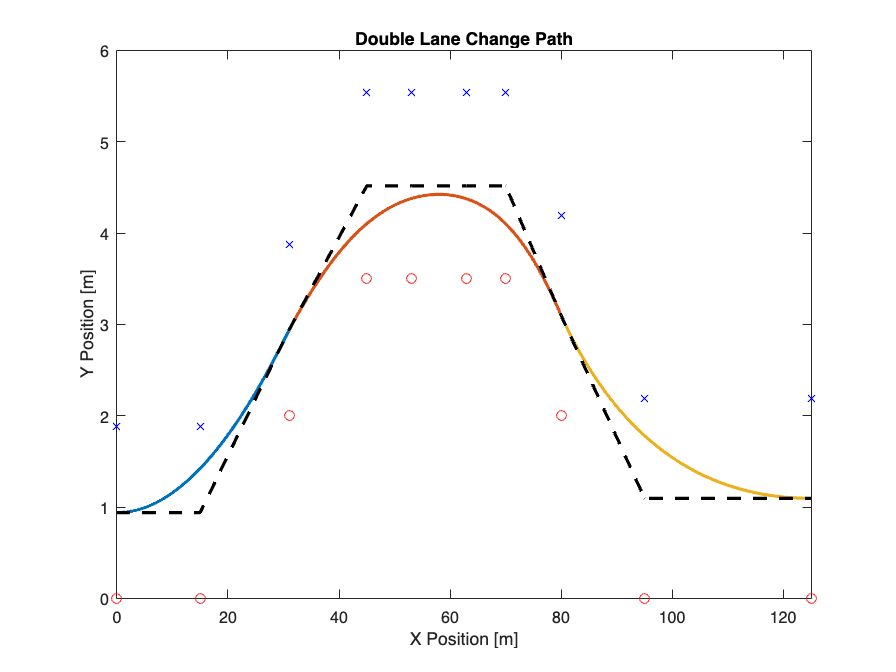

%Initialize the variables
Xp = [];
Yp = [];

%%%%%%%
%DOUBLE LANE CHANGE MANOEUVER - ISO 3888-1
%%%%%%%
Veh_width = 1.57; %For a Mid-size Sedan Vehicle, width in m
L1 = Veh_width*1.1+0.15;
L2 = Veh_width*1.2+0.15;
L3 = Veh_width*1.3+0.15;

p = []; %[x1 y1;x2 y2;x3 y3;...;xn yn]

%Change the points here to modify the shape of the curve.
%If you are adding new points, make sure you modify the p & p_ub_pts array
%points accordingly
p_lb_pts = [0,0; 15,0; 31,2; 45,3.5; 53,3.5; 63,3.5; 70,3.5; 80,2; 95,0; 125,0;]; %Points on the curve considering 0,0 starting point and no offset L1,L2,L3
%p_lb_pts = [0,0; 15,0; 31.25,1.95; 45,3.5; 53,3.5; 63,3.5; 70,3.5;81.75,1.95; 95,0; 125,0;]; % good path!
%p_lb_pts = [0,0; 15,0; 31,2; 45,3.5; 53,3.5; 63,3.5; 70,3.5; 80,2; 95,0;125,0;]; %best path so far

p_ub_pts = p_lb_pts;
p = p_lb_pts;

%Upper Bound
p_ub_pts(1:3,2) = p_lb_pts(1:3,2)+(L1); %Offset of the path. upper bound
p_ub_pts(4:7,2) = p_lb_pts(4:7,2)+(L2); %Offset of the path. upper bound
p_ub_pts(8:10,2) = p_lb_pts(8:10,2)+(L3); %Offset of the path. upper bound

%Mid-path
p(1:3,2) = p_lb_pts(1:3,2)+(L1/2); %Offset of the path to the centre of the vehicle
p(4:7,2) = p_lb_pts(4:7,2)+(L2/2); %Offset of the path to the centre of the vehicle
p(8:10,2) = p_lb_pts(8:10,2)+(L3/2); %Offset of the path to the centre of the vehicle

%Split the points into three bezier curves%

%Beizer Curves passes through first and last points and approximates
%through the middle points. This is the characteristic of the Beizer curve
p1 = p(1:3,:); 
p2 = p(3:8,:);
p3 = p(8:10,:);


[Xp_1,Yp_1] = bezier_curve(p1); %For first curve
[Xp_2,Yp_2] = bezier_curve(p2); %For second curve
[Xp_3,Yp_3] = bezier_curve(p3); %For third curve

Xp = [Xp_1(1:end-1); Xp_2(1:end-1); Xp_3(1:end-1);]; 
Yp = [Yp_1(1:end-1); Yp_2(1:end-1); Yp_3(1:end-1);];

figure(1001);
subplot(1,1,1)
plot(Xp_1(1:end-1),Yp_1(1:end-1),'Linewidth',2); hold on;
plot(Xp_2(1:end-1),Yp_2(1:end-1),'Linewidth',2); hold on;
plot(Xp_3(1:end-1),Yp_3(1:end-1),'Linewidth',2); hold on;

plot(p(:,1),p(:,2),'k--','Linewidth',2); hold on;  %Middle path
plot(p_ub_pts(:,1),p_ub_pts(:,2),'bx'); hold on;  %Upper points
plot(p_lb_pts(:,1),p_lb_pts(:,2),'ro'); hold on; %Lower points

xlabel('X Position [m]')
ylabel('Y Position [m]')
axis([0 125 0 6])
title('Double Lane Change Path')

The cirlces are lower bounds and the x's are upper bounds of the lanes, the curvatures must be mostly smooth so that the vehicle can actually follow the path. 

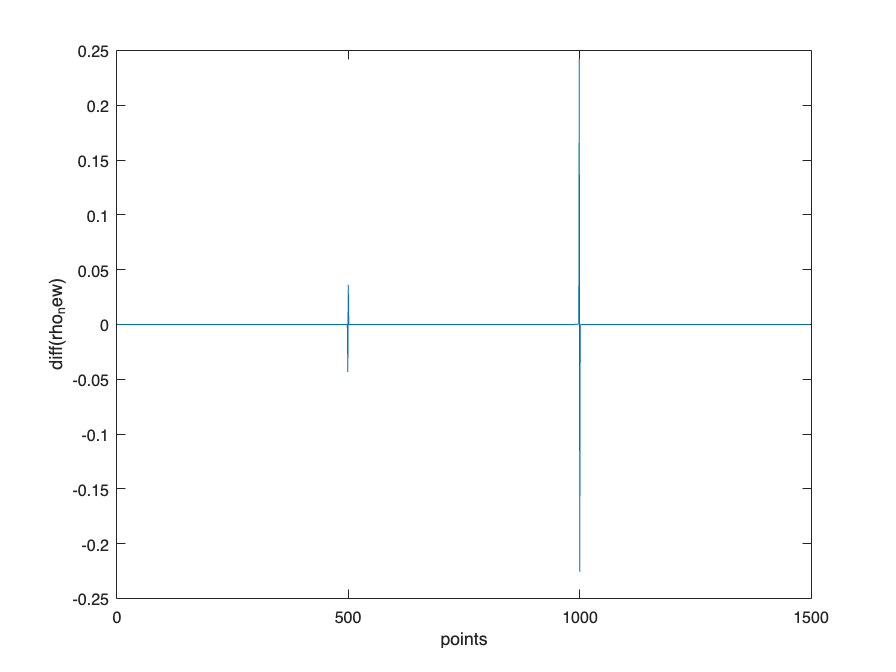

%Road Curvature Calculations

no_of_pts = length(Xp);
rho_ref = zeros(length(Xp)-1,1); %Create a Zero Vector for initialization

%Compute the Differentiation terms
del_1_Xp = diff(Xp);
del_1_Yp = diff(Yp);
del_2_Xp = diff(Xp,2); %Second order difference
del_2_Yp = diff(Yp,2); %Second order difference
del_pts = 1; %Difference in the index;

%Curvature Formula given in Lecture 21, Slide 27
rho_new = (((del_1_Xp(2:end)/del_pts).*(del_2_Yp/del_pts.^2))-((del_1_Yp(2:end)/del_pts).*((del_2_Xp/del_pts.^2))))./((del_1_Xp(2:end)./del_pts).^2+((del_1_Yp(2:end)./del_pts).^2)).^1.5;

%Calculation of total distance travelled for the lookuo table - xaxis input
Tot_d = 0;
for j = 1:no_of_pts-1
    d(j) = sqrt((Xp(j+1)-Xp(j))^2+(Yp(j+1)-Yp(j))^2);
    Tot_d = Tot_d+d(j);
    Cum_dis(j) = Tot_d; %Cumulative distance
end

dis_vec = Cum_dis(1:end-1); %Distance vector for the lookup table in the model
t_end = Tot_d/V; %for simulation time

% checking that the curvature slope is okay
figure
plot(diff(rho_new)); xlabel('points'), ylabel('diff(rho_new)')

# `Effect of speed, using the controller tuned for 5 m/s `

Varying vehicle velocity with the preview length of 2m

With the controller tuned for V = 5 m/s , the path is followed well at this speed, but, the following simulation results show that the controller must be retuned for different speed ranges. The path is less followed with a higher speed, and the path is over followed at a lower speed.

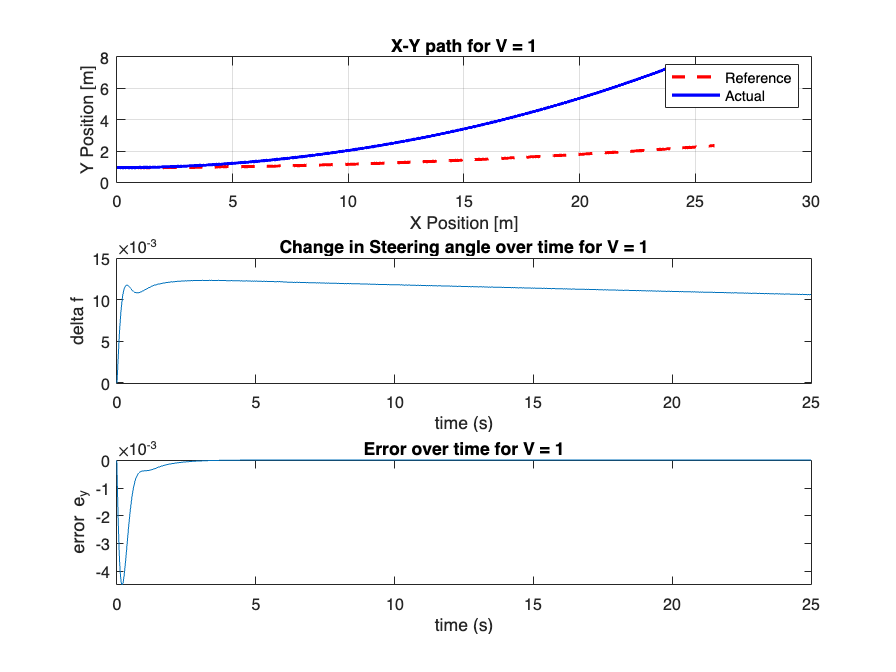

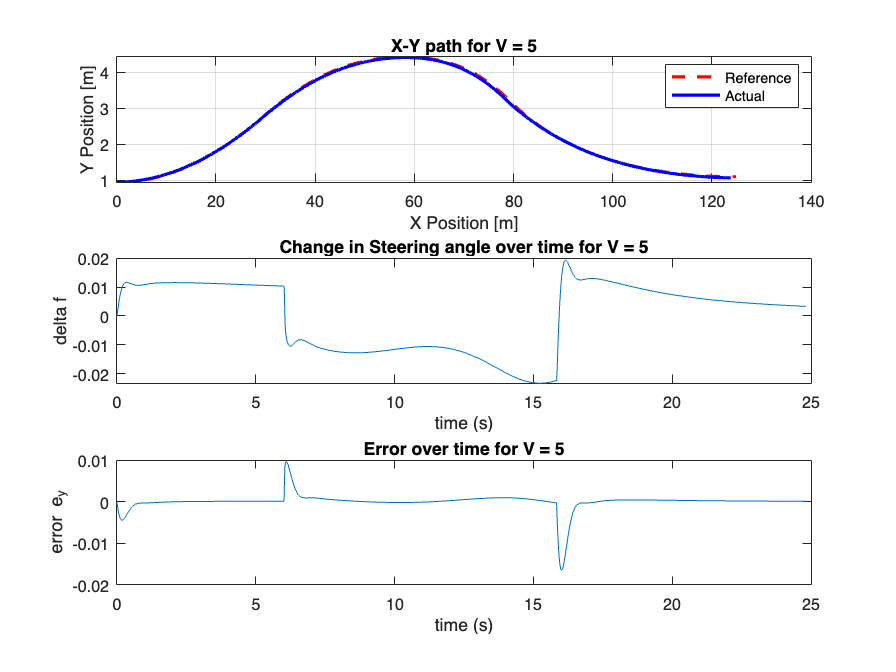

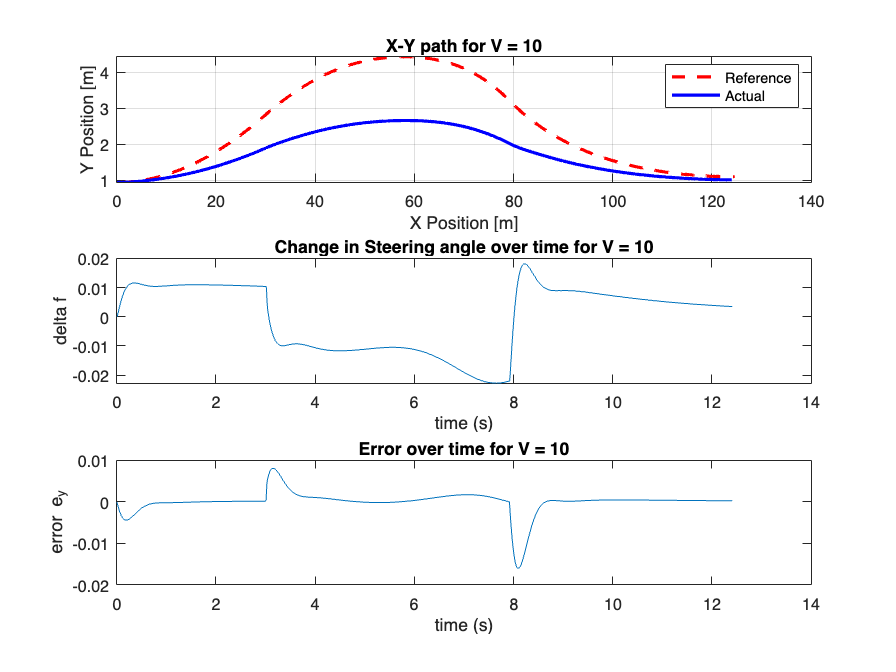

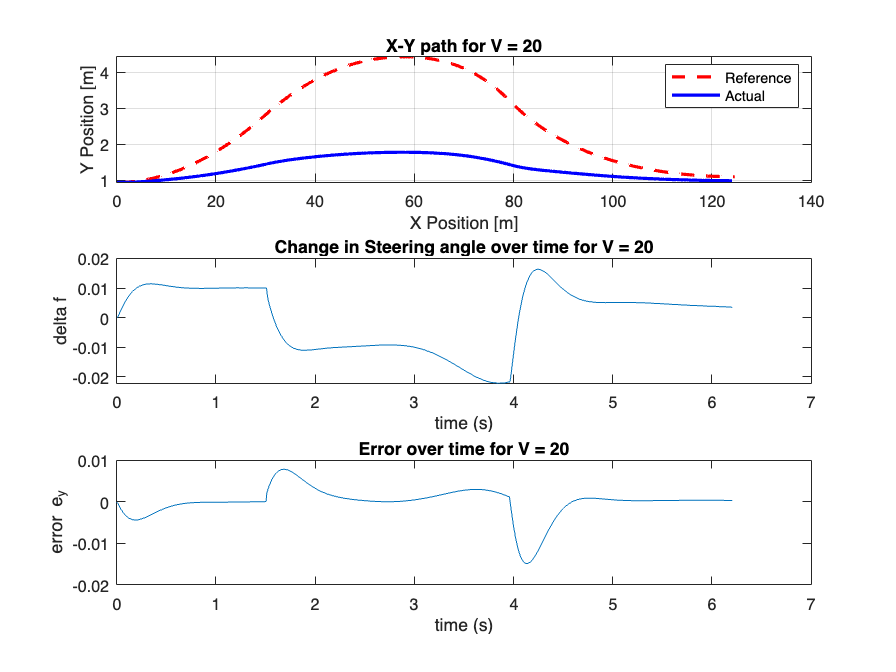

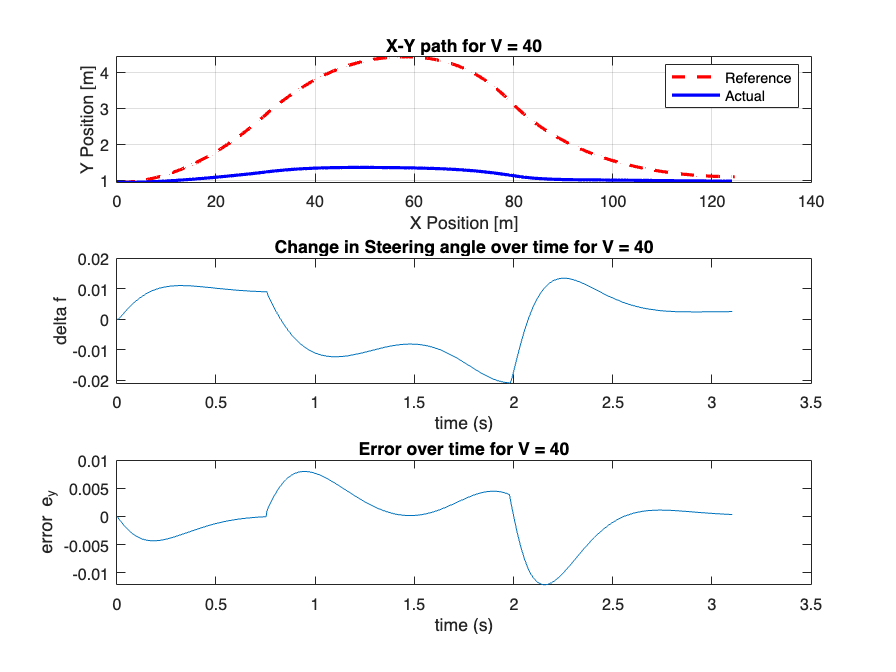

%%Operating condition
ls = 2; %Preview Distance [m]

loop = 1;
Velocities = [1,5,10,20,40];
n = length(Velocities);
for V = Velocities
    figure(), hold off
    
    sim('Path_following_Model_w_dbl_lane_change');

    % actual vs refrence path
    subplot(3,1,1) % 3 rows, n columns of graphs, and the index for the graph placement
    plot(X_ref,Y_ref,'r--','Linewidth',2); hold on; grid on; plot(X_actual,Y_actual,'b','Linewidth',2); grid on; hold off
    legend('Reference','Actual'),xlabel('X Position [m]'),ylabel('Y Position [m]'),title(['X-Y path for V = ', num2str(V)]);


    % plot Steering angle change 
    subplot(3,1,2)
    plot(time,delta_f_out)
    xlabel('time (s)'), ylabel('delta f'), title(['Change in Steering angle over time for V = ', num2str(V)]);

    
    % error
    subplot(3,1,3)
    plot(time,e_y_out)
    xlabel('time (s)'), ylabel('error e_y'), title(['Error over time for V = ', num2str(V)]);

    fig(loop) = gcf;

    loop = loop + 1;
end 

# `Effect of Preview Length `

Varying the preview length 			

input road curvature is “Both pulse” given in the Pulse input block. Plot Steering angle, road curvature disturbance and error 

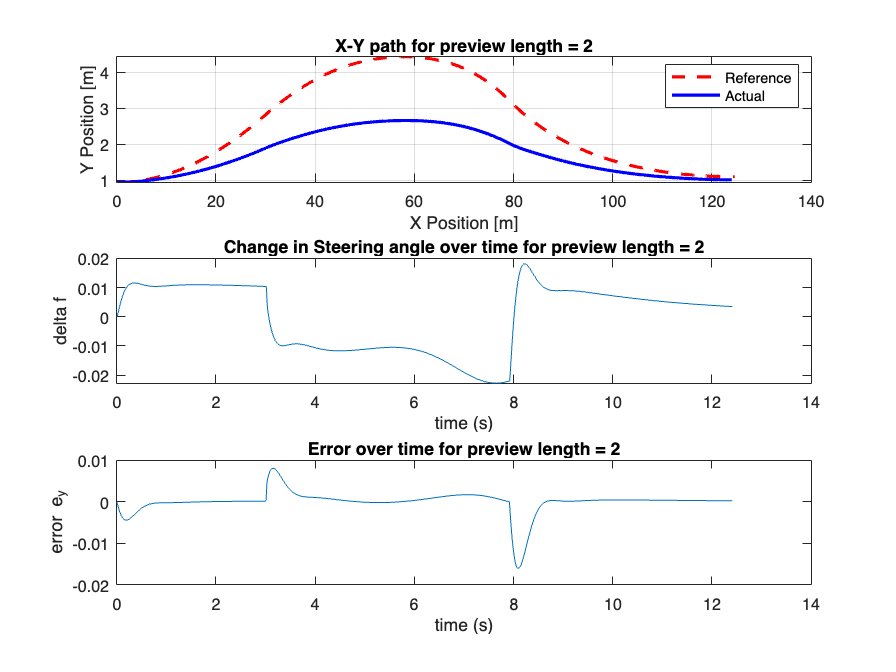

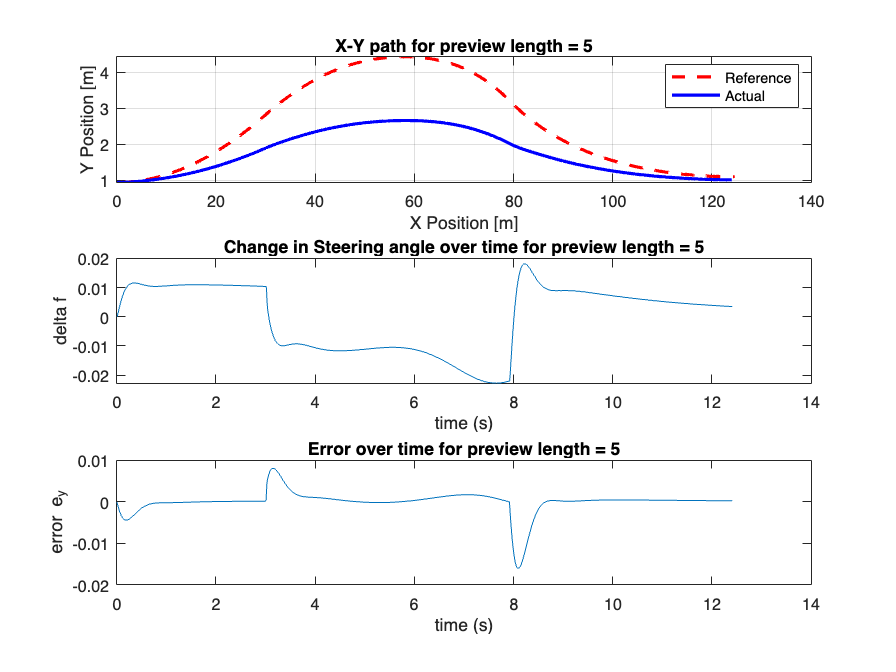

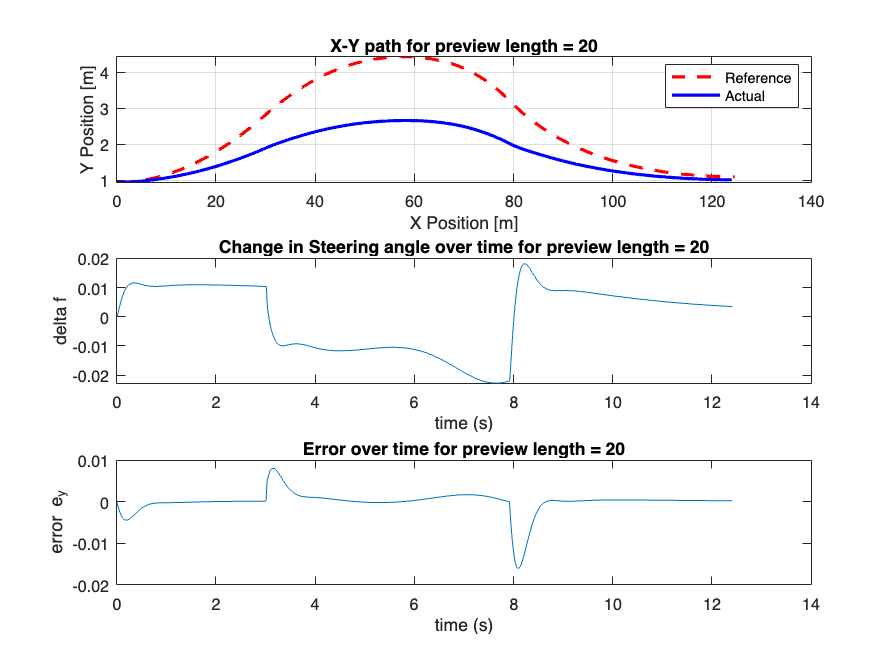

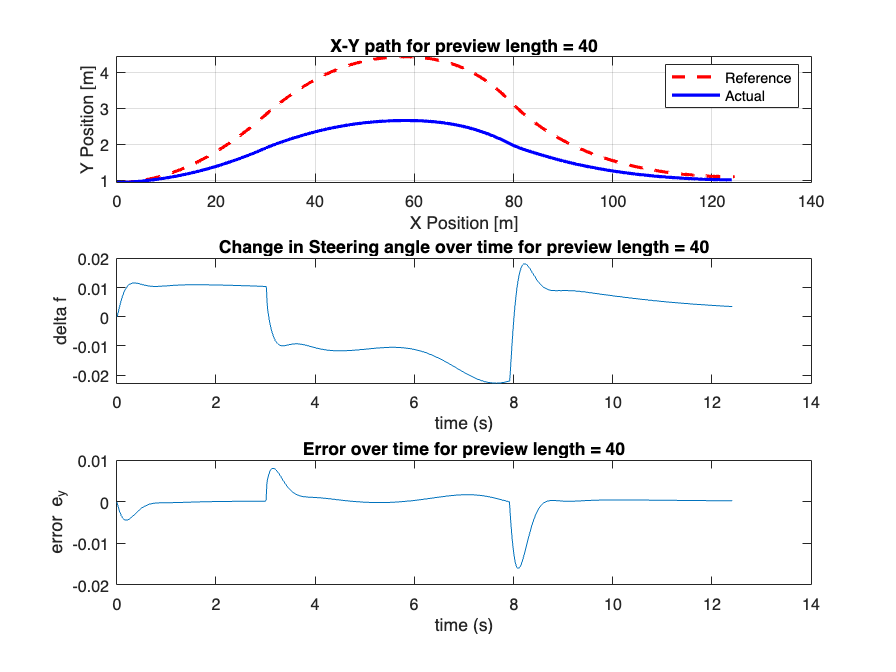

%%Operating condition
V = 10; % m/s

loop = 1;
previewLengths = [2,5,10,20,40];
n = length(previewLengths);
for ls = previewLengths
    figure(), hold off
    sim('Path_following_Model_w_dbl_lane_change');

    % actual vs refrence path
    subplot(3,1,1) % 3 rows, n columns of graphs, and the index for the graph placement
    plot(X_ref,Y_ref,'r--','Linewidth',2); hold on; grid on; plot(X_actual,Y_actual,'b','Linewidth',2); grid on; hold off
    legend('Reference','Actual'),xlabel('X Position [m]'),ylabel('Y Position [m]'),title(['X-Y path for preview length = ', num2str(ls)]);

    % plot Steering angle change 
    subplot(3,1,2)
    plot(time,delta_f_out)
    xlabel('time (s)'), ylabel('delta f'), title(['Change in Steering angle over time for preview length = ', num2str(ls)]);

    % error
    subplot(3,1,3)
    plot(time,e_y_out)
    xlabel('time (s)'), ylabel('error e_y'), title(['Error over time for preview length = ', num2str(ls)]);

    drawnow 

    fig(loop) = gcf;
    loop = loop + 1;
end

# `Conclusion `

    `The vehicle speed appears to be the defining characteristic of how well the path is followed, suggesting that the controller needs to be retuned for different speed ranges, perhaps through interpolation and a lookup table. Alternatively, the path needs to be more continuous, or a combination of both. The preview length was less important, its effect was difficult to determine, suggesting further analysis should be done. `

# Functions 

Vehicle Parameters

function [L, g, Lr, Lf, Cf, Cr, m, J, mu, R, Cs, V, ls, a11, a12, a21, a22, b11, b12, b21, b22, e2, A_matrix, B_matrix, C_matrix, D_matrix] = getModel()
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%ECE 5553 - Autonomy in Vehicles
    %%HW 4 - Path Following Linear Model
    %%Spring 2019
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    %%Vehicle Parameters
    L=2.85; % Distance between the axles [m]
    g=9.81; % 
    Lr = 1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle
    Lf = 1.3; % Distance from the center of gravity of the vehicle (CG) to the front axle
    Cf = 3e5; % Cornering Stiffness of Front Tires
    Cr = 3e5; % Cornering Stiffness of Rear Tires
    m = 2000; %Mass of the vehicle [kg]
    J = 3700; %Yaw moment of Inertia
    mu = 0.7; %Dry coefficient of Friction
    R = 0.3;
    Cs=1.5e5;
    
    %%Operating condition
    V = 5; %Longitudinal Velocity [m/s]
    ls = 2; %Preview Distance [m]
    
    %Linear Parameters Calculation
    a11 = -(Cr+Cf)/(m*V);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*V^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(V*J);
    b11 = Cf/(m*V); %Only Front wheel steering
    b12 = 0; %delta_r parameter
    b21 = Cf*Lf/J; %Only Front wheel steering
    b22 = 0; %delta_r parameter
    e2 = 1/J; % For yaw moment term - Not used in Path following model currently
    
    %%%%State Space Representation
    A_matrix = [a11 a12 0 0; a21 a22 0 0; 0 1 0 0; V ls V 0];
    B_matrix = [b11 0; b21 0; 0 -V; 0 -ls*V];
    C_matrix = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %Output is beta, r and ey
    D_matrix = [0 0; 0 0; 0 0; 0 0];
end 

Create a bezier curve between points

function [Xp,Yp] = bezier_curve(p1)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%ECE 5553 - Autonomy in Vehicles
    %%HW 4 - Path Following Linear Model
    %%Spring 2019
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%Bezier curve for higher order polynomials%
    % https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-837-computer-graphics-fall-2012/lecture-notes/MIT6_837F12_Lec01.pdf
    % Refer to Slide 62
    
    %   Detailed explanation goes here
    p = p1;
    
    n = length(p); %number of points
    n1=n-1;
    
    for i=0:1:n1
    sigma(i+1)=factorial(n1)/(factorial(i)*factorial(n1-i));  % for calculating (x!/(y!(x-y)!)) values 
    end
    l=[];
    UB=[];
    for u=0:0.002:1
        for d=1:n
        UB(d)=sigma(d)*((1-u)^(n-d))*(u^(d-1));
        end
    l=cat(1,l,UB);                                       
    end
    P=l*p;
    
    Xp = [P(:,1)]; %X_reference Points
    Yp = [P(:,2)]; %Y_reference Points
end
